# Daten Einlesen

clearvars;    % Löscht alle Variablen aus dem Workspace
close all;    % Schließt alle offenen Grafikfenster (Plots)
clc;          % Leert das Command Window (für die Übersicht)

filename = "Testdatensatz_6cm_60BPM_45s.txt";

% Kommas zu Punkten ersetzen (ohne Semikolons zu beeinflussen)
rawText = fileread(filename);                         % Originaltext lesen
cleanText = regexprep(rawText, '(?<=\d),(?=\d)', '.');% Nur Kommas zwischen Ziffern ersetzen

tempFilename = 'temp_log.txt';                        % Temporäre Datei
fid = fopen(tempFilename, 'w');                       % Datei zum Schreiben öffnen
fwrite(fid, cleanText);                               % Bereinigten Text schreiben
fclose(fid);                                          % Datei schließen

data = readmatrix(tempFilename, 'Delimiter', ';');

% Struktur erzeugen
accelerationX     = data(:,1);
accelerationY     = data(:,2);
accelerationZ     = data(:,3);
acc = data(:,4);
t                 = data(:,5);

## 1. Deine Ziel-Zeitachse (exakt 0.01s Schritte)

t_fix = t(1) : 0.01 : t(end);
df_fix = median(diff(t_fix));
f_fix = 1/df_fix;

## 2. Resampling durch Interpolation

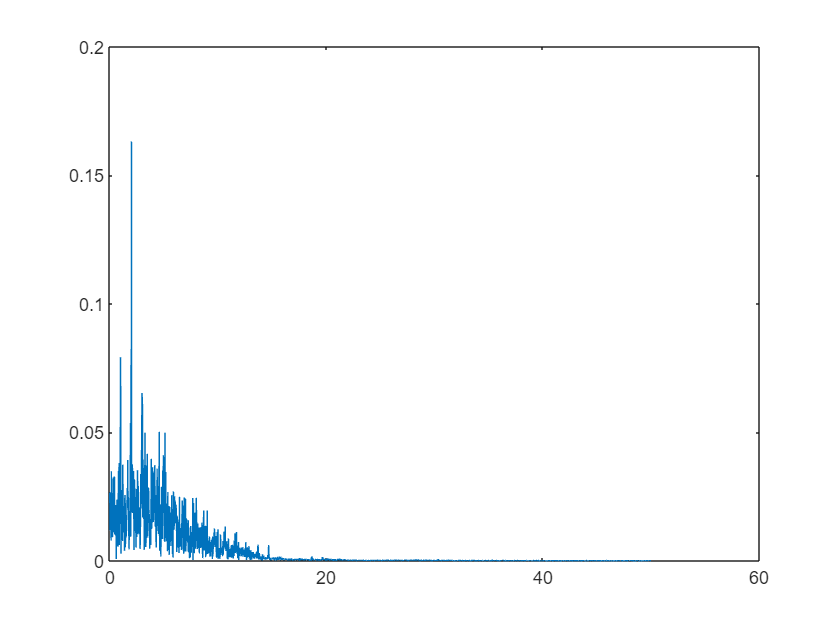

%FFT geht davon aus das die Daten gleichmäßig abgetastet sind, also
%gleicher zeitlicher Abstand
% Das "rettet" den Verlauf zwischen den unregelmäßigen Punkten
acc_100Hz = interp1(t, acc, t_fix, 'pchip'); % 'pchip' erhält die Kurvenform besser als 'linear'
med = median(acc_100Hz);
acc_100Hz = acc_100Hz - med; % Vorallem g =1 wird entfernt beim Sensor ist die Erdbeschleunigung = 1g Sensor misst g als Einheit
% Darstellen des Frequenzbereichs um die relevanten Siganteil zu
% untersuchen
[acc_fft, f_fft] = EinseitigesBetragsspektrum(f_fix, acc_100Hz);
%Mit offset man sieht starken Ausschlag auf der Nulllinie bis 1,2 hoch
figure;
plot(f_fft, acc_fft); 

(t)

## Interpolation Darstellung

Für DOkumentation welche Interpolationsmethode besser geeignet

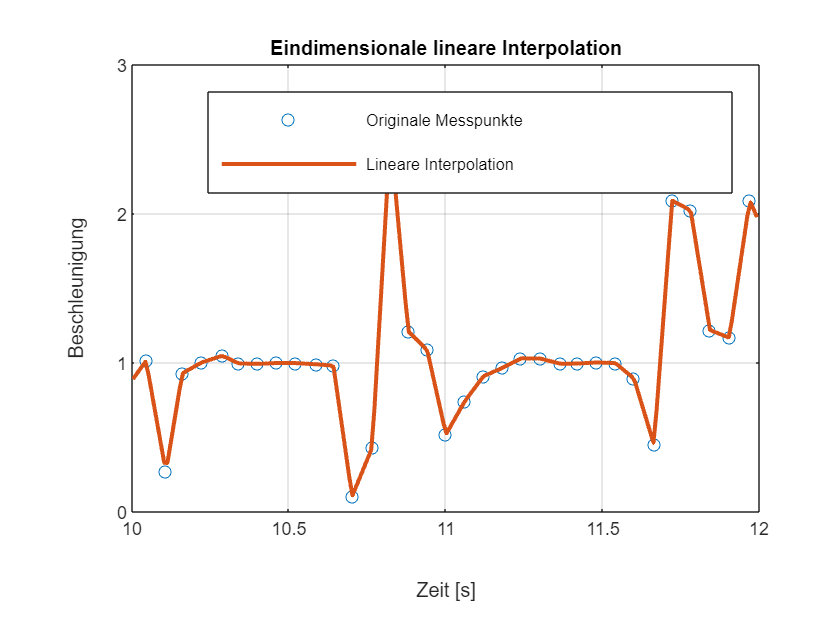


% künstliche Zeitachse
t_fix = t(1) : 0.01 : t(end);

% Lineare Interpolation mit Offset
acc_linear = interp1(t, acc, t_fix, 'linear');

% Ausschnitt wählen
t_start = 10;
t_end   = 12;

idx_raw = t >= t_start & t <= t_end;
idx_fix = t_fix >= t_start & t_fix <= t_end;

figure;
plot(t(idx_raw), acc(idx_raw), 'o', 'MarkerSize', 6);
hold on;
plot(t_fix(idx_fix), acc_linear(idx_fix), '-', 'LineWidth', 2);
grid on;

xlabel('Zeit [s]');
ylabel('Beschleunigung');
title('Eindimensionale lineare Interpolation');
legend('Originale Messpunkte', 'Lineare Interpolation');


% Probe: Rauschen entfernen 
%for n = 1:length(acc_100Hz)
%    if (-0.05 <= acc_100Hz(n)) && (acc_100Hz(n) <= 0.05)
 %       acc_100Hz(n) = 0;
 %   end
%en

%[acc_fft, f_fft] = EinseitigesBetragsspektrum(f_fix, acc_100Hz);
%figure;
%plot(f_fft, acc_fft);


## 3. Flowchart

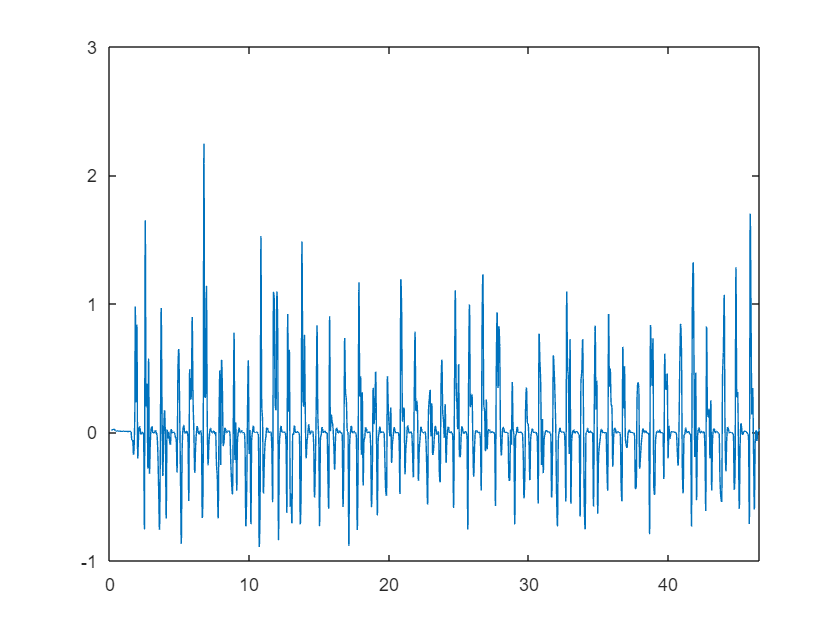

% 3. Jetzt folgt deine Kette aus dem Flowchart
% Tiefpass -> Integration -> Hochpass -> Integration -> Hochpass

% Wir arbeiten jetzt mit dem resampleten Signal
acc = acc_100Hz;
t1 = t_fix;

% Offset entfernen
med = median(acc);
acc = acc - med;

%abs macht alle Werte positiv
%Rauschen kleine unwichtige Schwankungen zu entfernen, SIgnal ist dauernd
%minimal am zittern
%acc(abs(acc) < 0.05) = 0;

% Probeplot der Daten
figure;
xlabel("Zeit");
ylabel("Beschleunigung");
title("Resampled Signal");
plot(t1, acc);

% Abschätzung der Abtastrate
%f_t = median(diff(t)); % Die durschnittliche Zeit vom Abstand der einzelnen Zeitpunkte ergibt die Abtastzeit.
%fs = 1 / f_t; % Die Abtastrate wird mittels der Abtastzeit bestimmt, da diese die Anzahl aller Werte pro Sekunde demonstriert wird als 1 / f_t verwendet.
%fs_ny = (1/f_t)/2;
fs = 100;
fs_ny = 50;

## Erste Filterung mit Tiefpass

Höhere Frequenzen durch Muskelzuckungen usw. Diese entfernen bzw. Signal glätten

(Glättung) mithilfe von Tiefpass Filter als Butterworth 2. Ordnung ->

Aufpassen nicht zu hohe Ordnung da ansonsten zu viel Rechenleistung entsteht und damit Ergebnisse Zeitverzögert antreten --> Schlecht für die geplante Echtzeitimplementierung

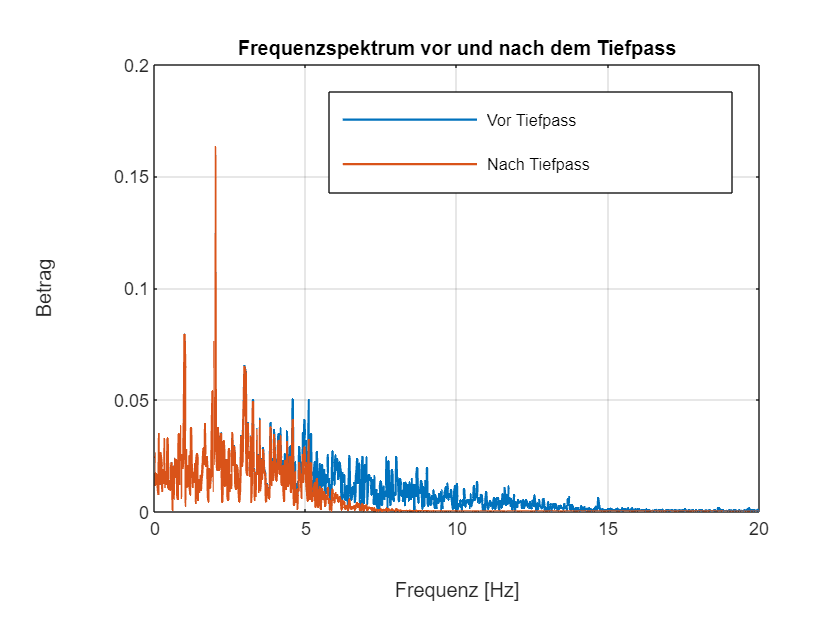

f_lg = 5.5; % gescheite Grenzfrequenz suchen (Literaturwerte durchsuchen um gewählten Wert zu rechtfertigen).
acc_before_lp = acc;

[b_1,a_1] = butter(4, f_lg/fs_ny, "low");
acc = filtfilt(b_1,a_1,acc); 

% Frequenzspektrum vor und nach dem Tiefpass
[acc_fft_before, f_fft_before] = EinseitigesBetragsspektrum(fs, acc_before_lp);
[acc_fft_after, f_fft_after] = EinseitigesBetragsspektrum(fs, acc);

figure;
plot(f_fft_before, acc_fft_before, 'LineWidth', 1.2);
hold on;
plot(f_fft_after, acc_fft_after, 'LineWidth', 1.2);
grid on;
xlabel('Frequenz [Hz]');
ylabel('Betrag');
title('Frequenzspektrum vor und nach dem Tiefpass');
legend('Vor Tiefpass', 'Nach Tiefpass');
xlim([0 20]);

## Erste Integration mittels Trapezregel

Hier wird Beschleunigung zu Geschwindigkeit 

Durch Integration erfolgt Addition von Fehler und Rauschen durch Sensorungenauigkeit, weshalb dieser wachsender Fehler immer größer wird --> Drift

Niederfrequentes Rauschen/Fehler wachsen, hochfrequentes geht schnell hoch und runter hebt sich gegenseitig auf. durch Hochpass Drift Entfernung 

velocity = cumtrapz(t1,acc); % Numerische Integration mittels Trapezregel auch in Paper nachzulesen


f_hg = 0.9 ;
%[z, p, k] = butter(2, f_hg/(fs/2), 'high');
%sos = zp2sos(z, p, k);
%velo_new = sosfilt(sos, velocity);
%filtfilt bei Real time nicht möglich da zuküntige Werte fehlen.
%Auch hier gescheite Literaturwerte Suchen um Werte zu rechtfertigen, vlt in den Leitlinien ersichtbar.
[b_2,a_2] = butter(2, f_hg/fs_ny, "high");
velo_new = filtfilt(b_2,a_2, velocity);




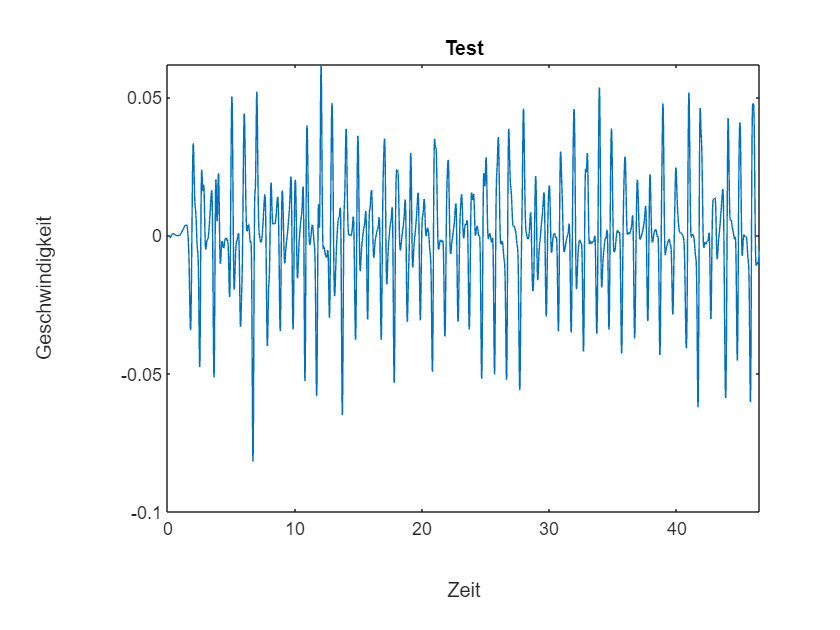

% Plot der Geschindigkeiten nach DC-Anteil Entfernung
figure;
plot(t1, velo_new);
xlabel("Zeit");
ylabel("Geschwindigkeit");
title("Test")

## Zweite Inetgration mittels Trapezregel

Die zweite Integration wird ebenfalls mit der Trapezregel durchgeführt

Fehlerakkumulation:

Ebenso Driftentfernung durch Hochpass, dabei wie in Dokumentation beschrieben mehrere Ordnungen und Grenzfrequenzen untersucht im Frequenzbereich.

Tiefe = cumtrapz(t1,velo_new); 

% Gleich wie Oben fehleraddition welcher mittels Hochpass entfernt wird.
%Integration erzeugt Fehlerakkumulation
% Signal vor dem zweiten Hochpass speichern
depth_before_hp = Tiefe;
f_hg_1 = 0.5 ; %Auch hier gescheite Literaturwerte Suchen um Werte zu rechtfertigen, vllt in den Leitlinien ersichtbar.
%[z, p, k] = butter(2, f_hg_1/(fs/2), 'high');
%sos = zp2sos(z, p, k); % Hochpass um den DC-Anteil von den geringen Frequenzen als Artefakte zu entfernen, bevor dieser exponential mittels Doppelintegration wächst.
%depth_new = sosfilt(sos, depth);
[b_2, a_2] = butter(2, f_hg_1/fs_ny,"high"); % Hochpass um den DC-Anteil von den geringen Frequenzen als Artefakte zu entfernen, bevor dieser exponential mittels doppelintegration wächst.
depth_new = filtfilt(b_2, a_2, Tiefe);

%Frequenzbereich Untersuchung
% Frequenzspektrum vor und nach dem Hochpass
[depth_fft_before, f_depth_before] = EinseitigesBetragsspektrum(fs, depth_before_hp);
[depth_fft_after, f_depth_after] = EinseitigesBetragsspektrum(fs, depth_new);

figure;
plot(f_depth_before, depth_fft_before, 'LineWidth', 1.2);
hold on;
plot(f_depth_after, depth_fft_after, 'LineWidth', 1.2);
grid on;
xlabel('Frequenz [Hz]');
ylabel('Betrag');
title('Frequenzspektrum vor und nach dem Hochpass des Wegsignals');
legend('Vor Hochpass', 'Nach Hochpass');
xlim([0 5]);

## Plot von den Tiefenergebnisse

Sensor liefert Beschleunigung in g, das wurde durch ein Test herausgefunden der in der Dokumentation beschrieben ist.

Nach der Integration wird deshalb mit 9.81 von g nach m/s² umgerechnet

Anschließend Umrechnung von Meter in Zentimeter

Maxima und darauffolgendes Minima finden.

Für die Minima Signal invertieren das Minima zu Maxima werden

Tiefe = Maxima(Entlastung des Brustkorbs) - Minima(komprimierter Zustand des Brustkorbs)

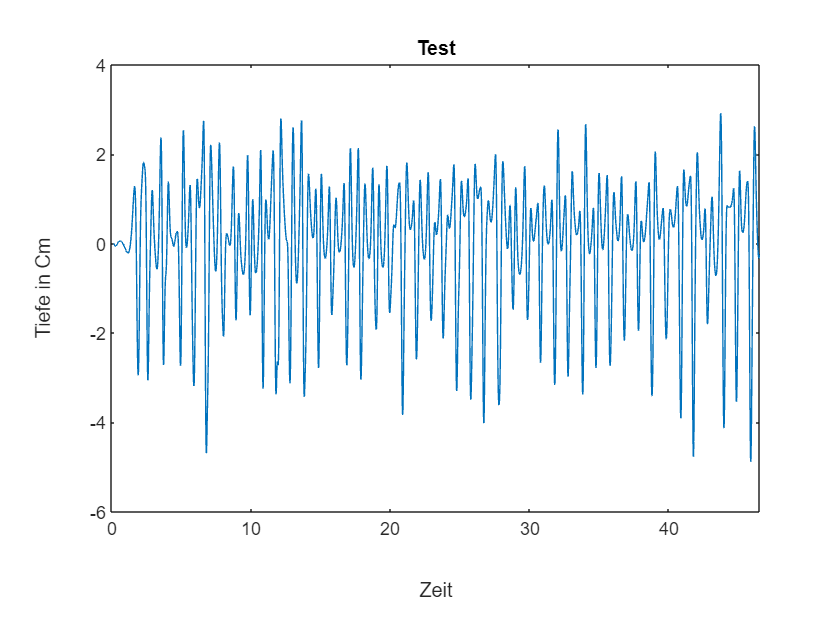

depth_rdy = depth_new * 9.81 * 100;
figure;
plot(t1, depth_rdy);
xlabel("Zeit");
ylabel("Tiefe in Cm");
title("Test");

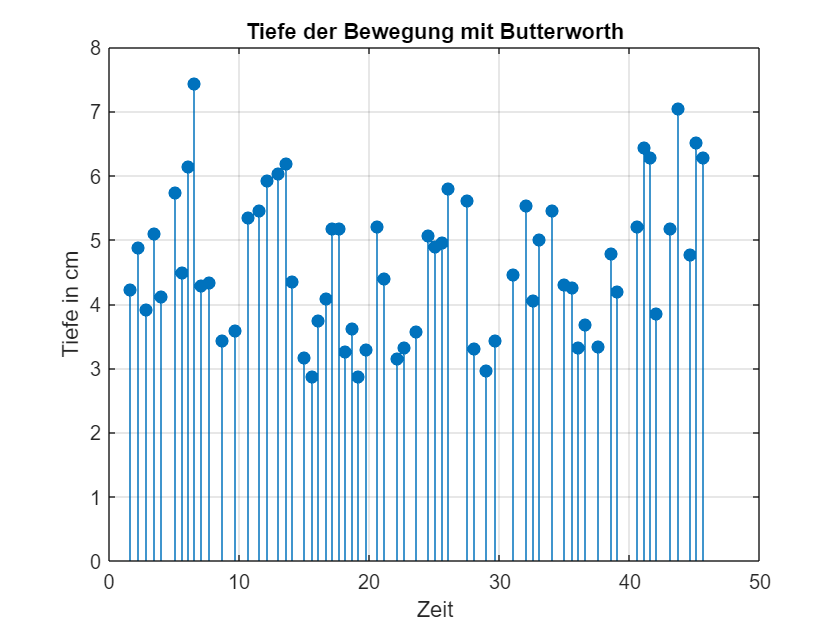

% Lokale Maxima finden
[maxima, maxIdx] = findpeaks(depth_rdy,'MinPeakHeight', 1.0,'MinPeakDistance', round(0.4*fs));

% Lokale Minima finden
[minima_neg, minIdx] = findpeaks(-depth_rdy,'MinPeakHeight', 1.0, 'MinPeakDistance', round(0.4*fs));
minima = -minima_neg;

% Vektoren für CPR-Tiefe und zugehörige Zeitpunkte
ccd = [];
ccd_time = [];

for i = 1:length(maxIdx)
    nextMaxIdx = maxIdx(i);

    % erstes Minimum nach diesem Maximum suchen
    nextMinCandidates = minIdx(minIdx > nextMaxIdx);

    if isempty(nextMinCandidates)
        break;
    end

    nextMinIdx = nextMinCandidates(1);

    % Kompressionstiefe berechnen
    ccdVal = maxima(i) - minima(minIdx == nextMinIdx);

    % alternativ robust direkt aus Signals
    % ccdVal = depth_rdy(nextMaxIdx) - depth_rdy(nextMinIdx);

    ccd(end+1) = ccdVal;

    % Zeit des Peaks speichern
    ccd_time(end+1) = t1(nextMaxIdx);
end

% Plot wie in der Dissertation: einzelne Peaks / Einzelwerte
figure;
stem(ccd_time, ccd, 'filled');
xlabel("Zeit");
ylabel("Tiefe in cm");
title("Tiefe der Bewegung mit Butterworth");
grid on;

Höhe der Peaks nicht konstant absolut normal weil menschliche Bewegung nie perfekt konstant sein kann. Deshalb auch unsere Datensätze fehlerbehaftet, weil von Hand aufgenommen. 

## Kompressionsfrequenz

Kompressionsfrequenz in Kompressionen pro Minute

Zeitabstand = diff(ccd_time);
Frequenz = 60 ./ Zeitabstand;
Durchschnittfrequenz = mean(Frequenz);
fprintf('Mittlere Kompressionsfrequenz: %.1f Kompressionen/min\n',Durchschnittfrequenz);

Mittlere Kompressionsfrequenz: 94.6 Kompressionen/min


## Quantitaive Analyse

Aber für den Quantitativen Vergleich wurden diesselben Datensätze für die Quantitative Analyse des KI-basierten- Ansatz und der Quantitativen Analyse des Signalverarbeitungs-Ansatz verwendet.

## Quantitative Analyse der Tiefe

- **zu flach:** unter 4,5 cm

- **perfekt:** 4,5 cm bis 5,5 cm 

- **zu tief:** über 5,5 cm

label = "Tief";
perfekt = 0;
Tief = 0;
Flach = 0;

for i = 1:length(ccd)
    if ccd(i) > 5.5
        Tief = Tief + 1;
    elseif ccd(i) < 4.5
        Flach = Flach + 1;
    else 
        perfekt = perfekt + 1;
    end
end


if label == "Perfekt"
    N = perfekt + Flach + Tief;
    fprintf("Genauigkeit der Drucktiefe: %.2f%%",(perfekt/N)*100);
end
if label == "Flach"
    N = perfekt + Flach + Tief;
    fprintf("Genauigkeit der Drucktiefe: %.2f%%", (Flach/N)*100);
end

if label == "Tief"
    N = perfekt + Flach + Tief;
    fprintf("Genauigkeit der Drucktiefe: %.2f%%", (Tief/N)*100);
end

Genauigkeit der Drucktiefe: 22.22%

## Quantitative Analyse der Frequenz

**zu langsam:** unter 100 Kompressionen/min

**perfekt:** 100 bis 120 Kompressionen/min 

**zu schnell:** über 120 Kompressionen/min

label_freq = "Langsam";   % mögliche Werte: "Perfekt", "Langsam", "Schnell"

perfekt_freq = 0;
Langsam = 0;
Schnell = 0;

for i = 1:length(Frequenz)

    if Frequenz(i) < 100
        Langsam = Langsam + 1;

    elseif Frequenz(i) > 120
        Schnell = Schnell + 1;

    else
        perfekt_freq = perfekt_freq + 1;
    end
end

N_freq = perfekt_freq + Langsam + Schnell;

if label_freq == "Perfekt"
    fprintf("Genauigkeit der Kompressionsfrequenz: %.2f%%\n",(perfekt_freq/N_freq)*100);
end

if label_freq == "Langsam"
    fprintf("Genauigkeit der Kompressionsfrequenz: %.2f%%\n",(Langsam/N_freq)*100);
end

Genauigkeit der Kompressionsfrequenz: 46.77%



if label_freq == "Schnell"
    fprintf("Genauigkeit der Kompressionsfrequenz: %.2f%%\n",(Schnell/N_freq)*100);
end